# Plot from the data of main

    % If you want to use the workspace data, make this value true
useWorkspaceData = true;

if useWorkspaceData == false
    clear all;
    clc;
    warning('off');
    useWorkspaceData = false;
end

## Selecting the data

testData = false;

#### Select data name and folder

    %% TEST DATA
if testData == true 
    fileName = "testing.mat";
    folderName = "..\output\testing";
    pathName = fullfile(folderName, fileName);
else
    %% CHOOSEN DATA

    fileName = "Rl_5.0_Ra_0.1_test_direct.mat";
    folderName = "..\output\opt\R";
    pathName = fullfile(folderName, fileName);
end

if useWorkspaceData == false
    load(pathName);
end

#### Total time of the simulation in seconds

disp("Total time: " + num2str(step_time(i)) + " seconds");

Total time: 861.6685 seconds


## Dynamic plot

% figure; 
% set(gcf,'Visible','on'); hold on; grid on;
% sp = SystemPlotter(leaderParams, followerParams, x_l(:,1), x_f(:, 1), N, obstacles);
% tit = title("Iteration 1, time: 0s");
% 
% for ip = 1 : i - 1
% 
%         % Do the plotting
%     sp.updateLeaderPath(x_l(:,ip), X_L_plot(:,:,ip));
%     sp.updateLoadPos(x_l(:,ip), x_f(:,ip), loadTheta_p(ip) - pi/4);
%     sp.updateFollowerPath(x_f(:,ip), X_F_plot(:,:,ip));
% 
%     if size(obstacles, 1) ~= 0
%         sp.updateObstacles(obstacles, size(obstacles, 1))
%     end
% 
%     tit.String = "Iteration: " + num2str(ip) + ", time: " + num2str(ip*sys.Ts) + "s";
%     sp.redraw();
% end

#### Save gif

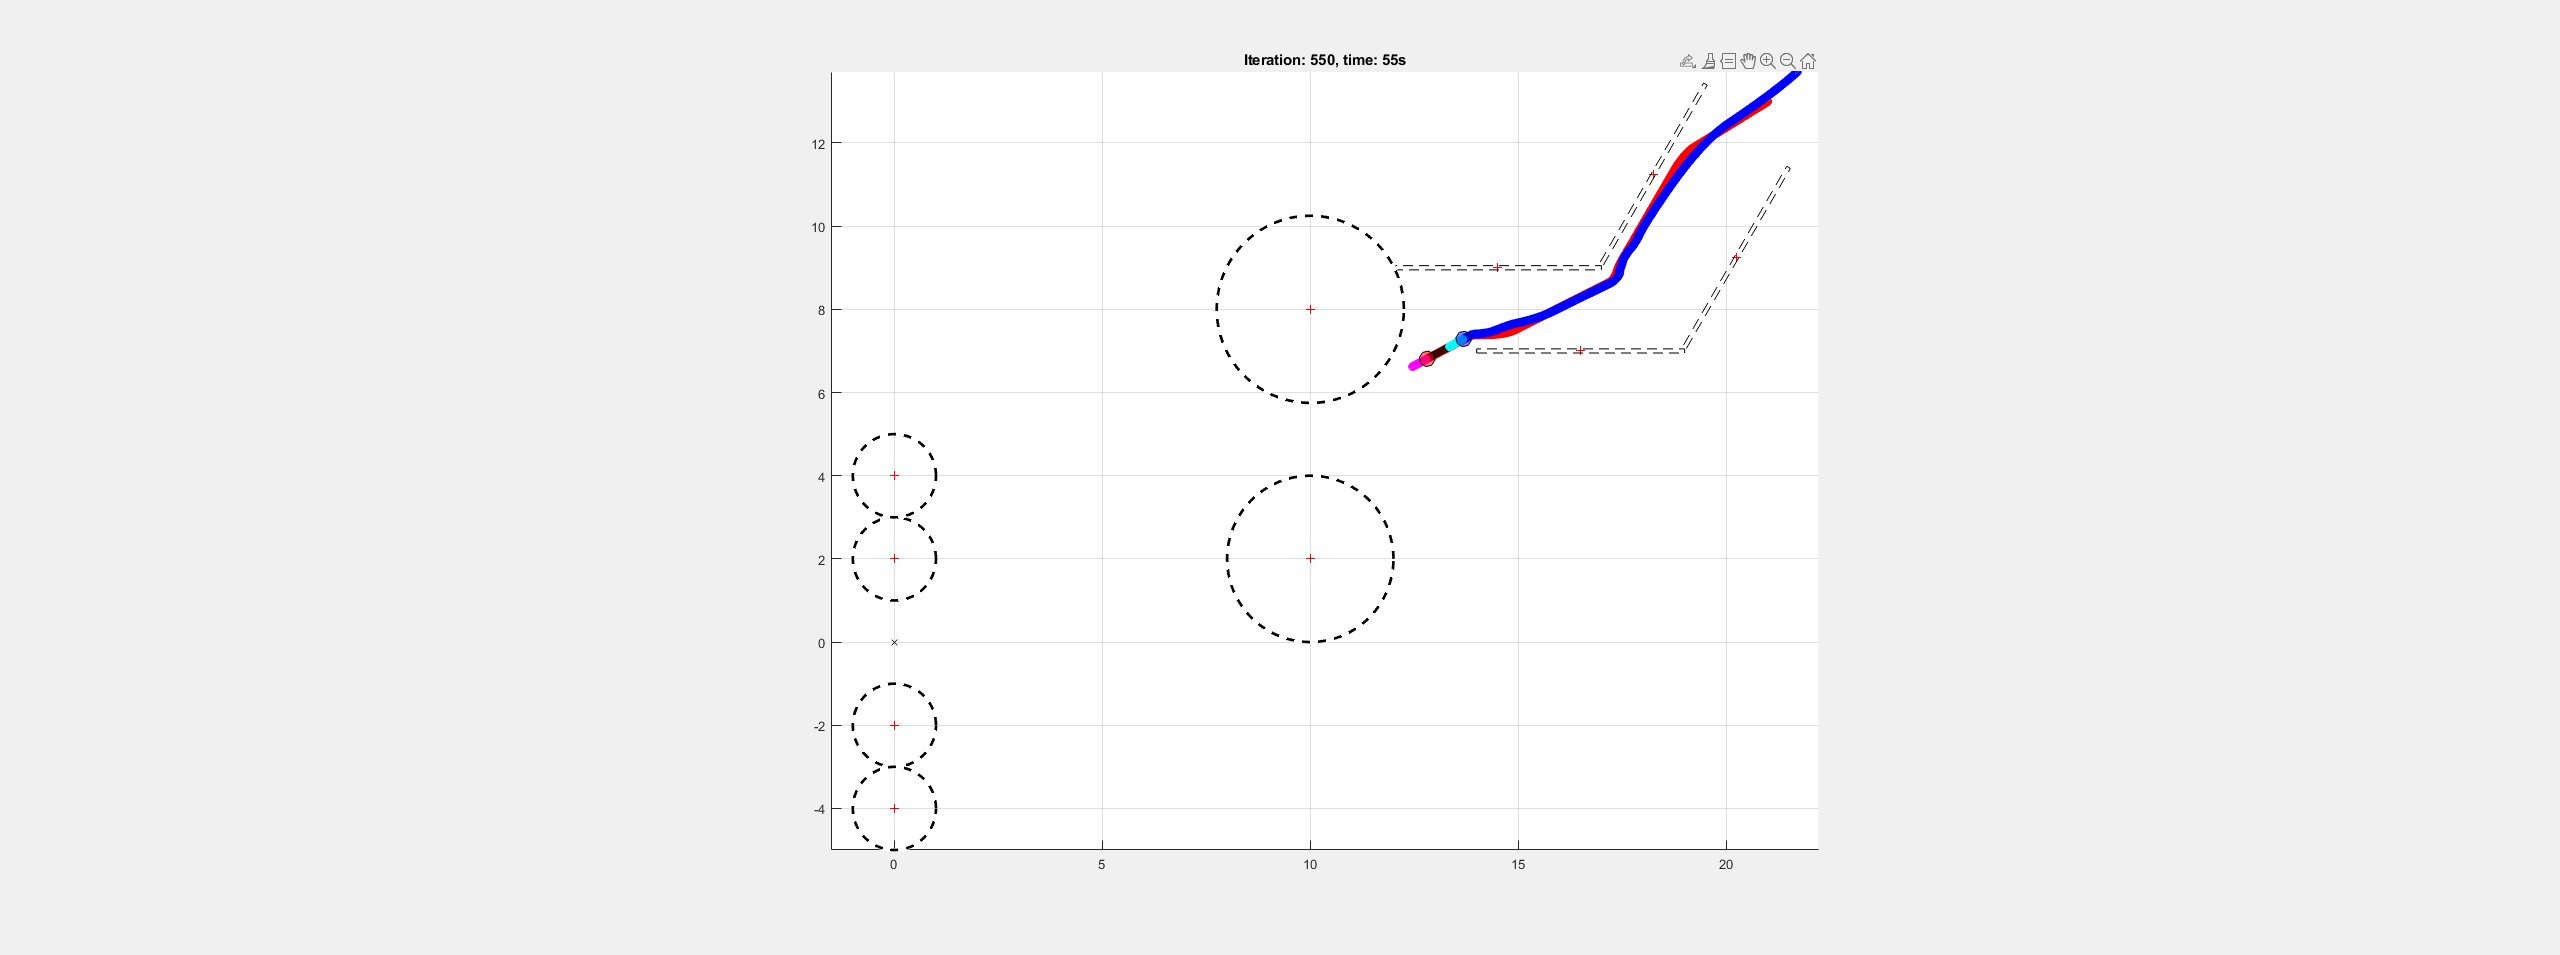

gifName = 'dynamic_' + environmentName + '.gif'; 
gifPath = fullfile(folderName, gifName);
frame_delay = sys.Ts;
hFig = figure("WindowState", "maximized"); 

set(hFig,'Visible','on','PaperOrientation', 'landscape'); 
hold on; grid on; axis equal;
sp = SystemPlotter(leaderParams, followerParams, loadParams, x_l(:,1), x_f(:, 1), N, obstacles, goal);
tit = title("Iteration 1, time: 0s");

for ip = 1 : i - 1

    % Do the plotting
    sp.updateLeaderPath(x_l(:,ip), X_L_plot(:,:,ip));
    sp.updateFollowerPath(x_f(:,ip), X_F_plot(:,:,ip));
    sp.updateLoadPos(x_l(:,ip), x_f(:,ip), loadTheta_p(ip));

    % if size(obstacles, 1) ~= 0
    %     sp.updateObstacles(obstacles, size(obstacles, 1))
    % end
    
    tit.String = "Iteration: " + num2str(ip) + ", time: " + num2str(ip*sys.Ts) + "s";
    sp.redraw();

    drawnow
    frame = getframe(hFig);
    im = frame2im(frame);
    [A, map] = rgb2ind(im, 256);

    if ip == 1
        imwrite(A, map, gifPath, 'gif', 'LoopCount', Inf, 'DelayTime', frame_delay);
    else
        imwrite(A, map, gifPath, 'gif', 'WriteMode', 'append', 'DelayTime', frame_delay);
    end
end

## Results plot

time = 0:sys.Ts:sys.Ts*(i-1);

load = x_f(1:2,i)+loadParams.loadShape;

#### Trajectory plot

subplot(4,2,[1 3 5 7])
hold on; grid on;
axis equal;
plot( x_l(1,1:i), x_l(2,1:i), "-o","Color", "red");
plot( x_f(1,1:i), x_f(2,1:i), "-o","Color", "blue")
plotObstacles(obstacles);
plot(polyshape(load'), 'FaceColor',loadParams.color,'FaceAlpha',0.75);
title("\textbf{Leader-Follower Trajectory}","Interpreter","latex", "FontSize", 14)
xlabel("Coordinate x [m]","Interpreter","latex", "FontSize", 12)
ylabel("Coordinate y [m]","Interpreter","latex", "FontSize", 12)
legend("Leader Robot","Follower Robot","Location","southeast","Interpreter","latex", "FontSize", 12)

#### Coordinates evolution plot

subplot(4,2,2)
hold on; grid on;
axis normal;
plot(time, x_l(1,1:i), "-r", time, x_l(2,1:i), "-b");
plot(time, x_f(1,1:i), "--r", time, x_f(2,1:i), "--b");
xlabel("Time [s]", "Interpreter","latex","FontSize", 12)
ylabel("$p_x$/$p_y$ [m]", "Interpreter","latex", "FontSize", 12)
title("\textbf{Coordinates evolution}", "Interpreter","latex", "FontSize", 14)
legend("$p_{L,x}$","$p_{L,y}$","$p_{F,x}$","$p_{F,y}$","Interpreter","latex", "FontSize", 12)

#### Formation error plot

subplot(4,2,4)
plot(time(1:end-1),real_d(1:i-1) - followerParams.d_FL);
grid on;
axis normal;
xlabel("Time [s]", "Interpreter","latex", "FontSize", 12)
ylabel("$error$ [m]", "Interpreter","latex", "FontSize", 12)
title("\textbf{Formation error}", "Interpreter","latex", "FontSize", 14)

#### Linear velocities plot

subplot(4,2,6)
hold on; grid on;
axis normal;
plot(time, u_l(1,1:i));
plot(time, u_f(1,1:i));
xlabel("Time [s]", "Interpreter","latex","FontSize", 12)
ylabel("$v$ [m/s]", "Interpreter","latex", "FontSize", 12)
title("\textbf{Linear velocities evolution}", "Interpreter","latex", "FontSize", 14)
legend("$v_{L}$","$v_{F}$","Interpreter","latex", "FontSize", 12)

#### Angular velocities plot

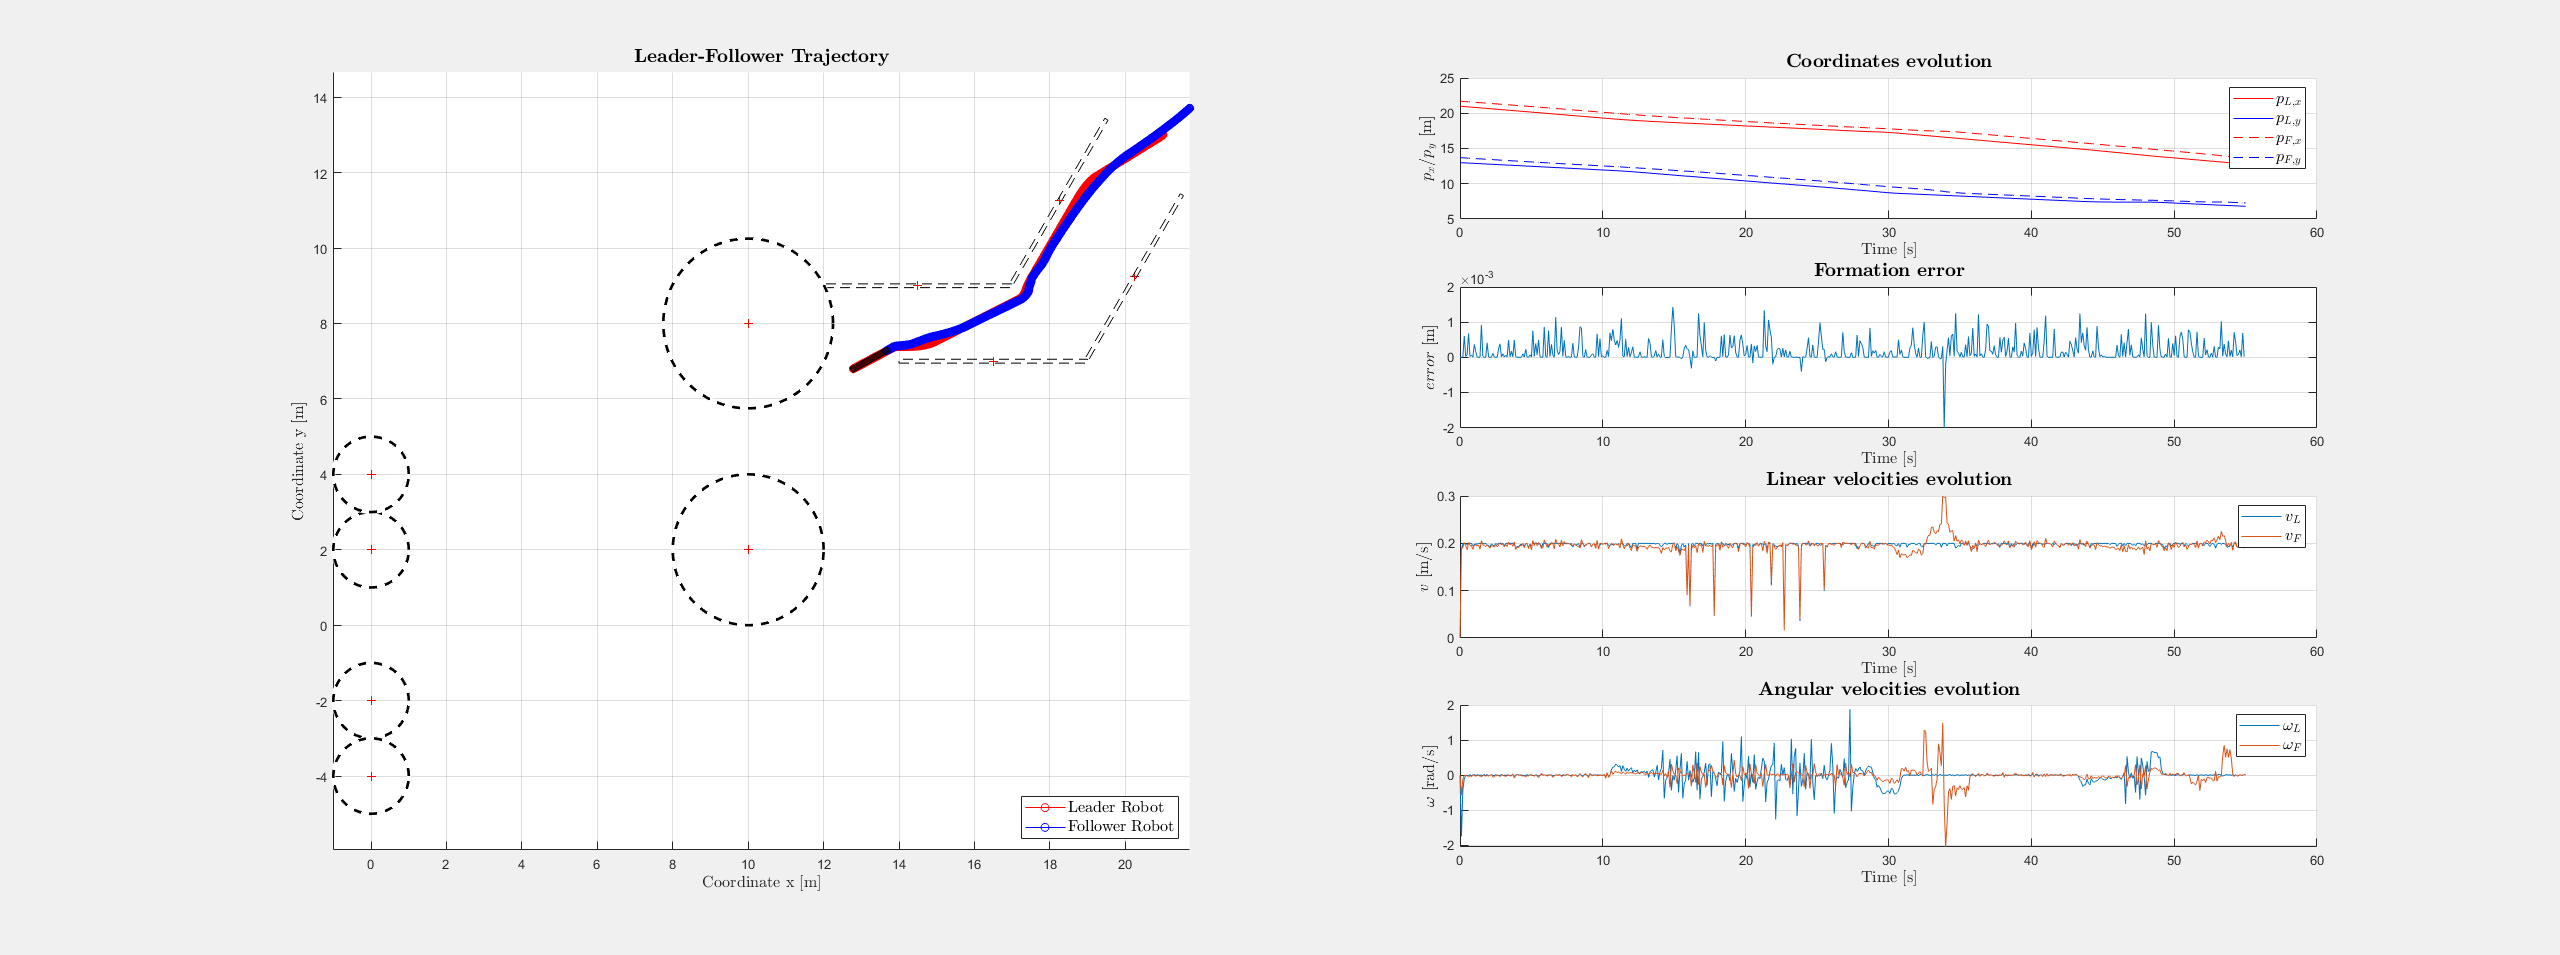

subplot(4,2,8)
hold on; grid on;
axis normal;
plot(time, u_l(2,1:i), "-");
plot(time, u_f(2,1:i), "-");
xlabel("Time [s]", "Interpreter","latex","FontSize", 12)
ylabel("$\omega$ [rad/s]", "Interpreter","latex", "FontSize", 12)
title("\textbf{Angular velocities evolution}", "Interpreter","latex", "FontSize", 14)
legend("$\omega_{L}$","$\omega_{F}$","Interpreter","latex", "FontSize", 12)

## Saving plots

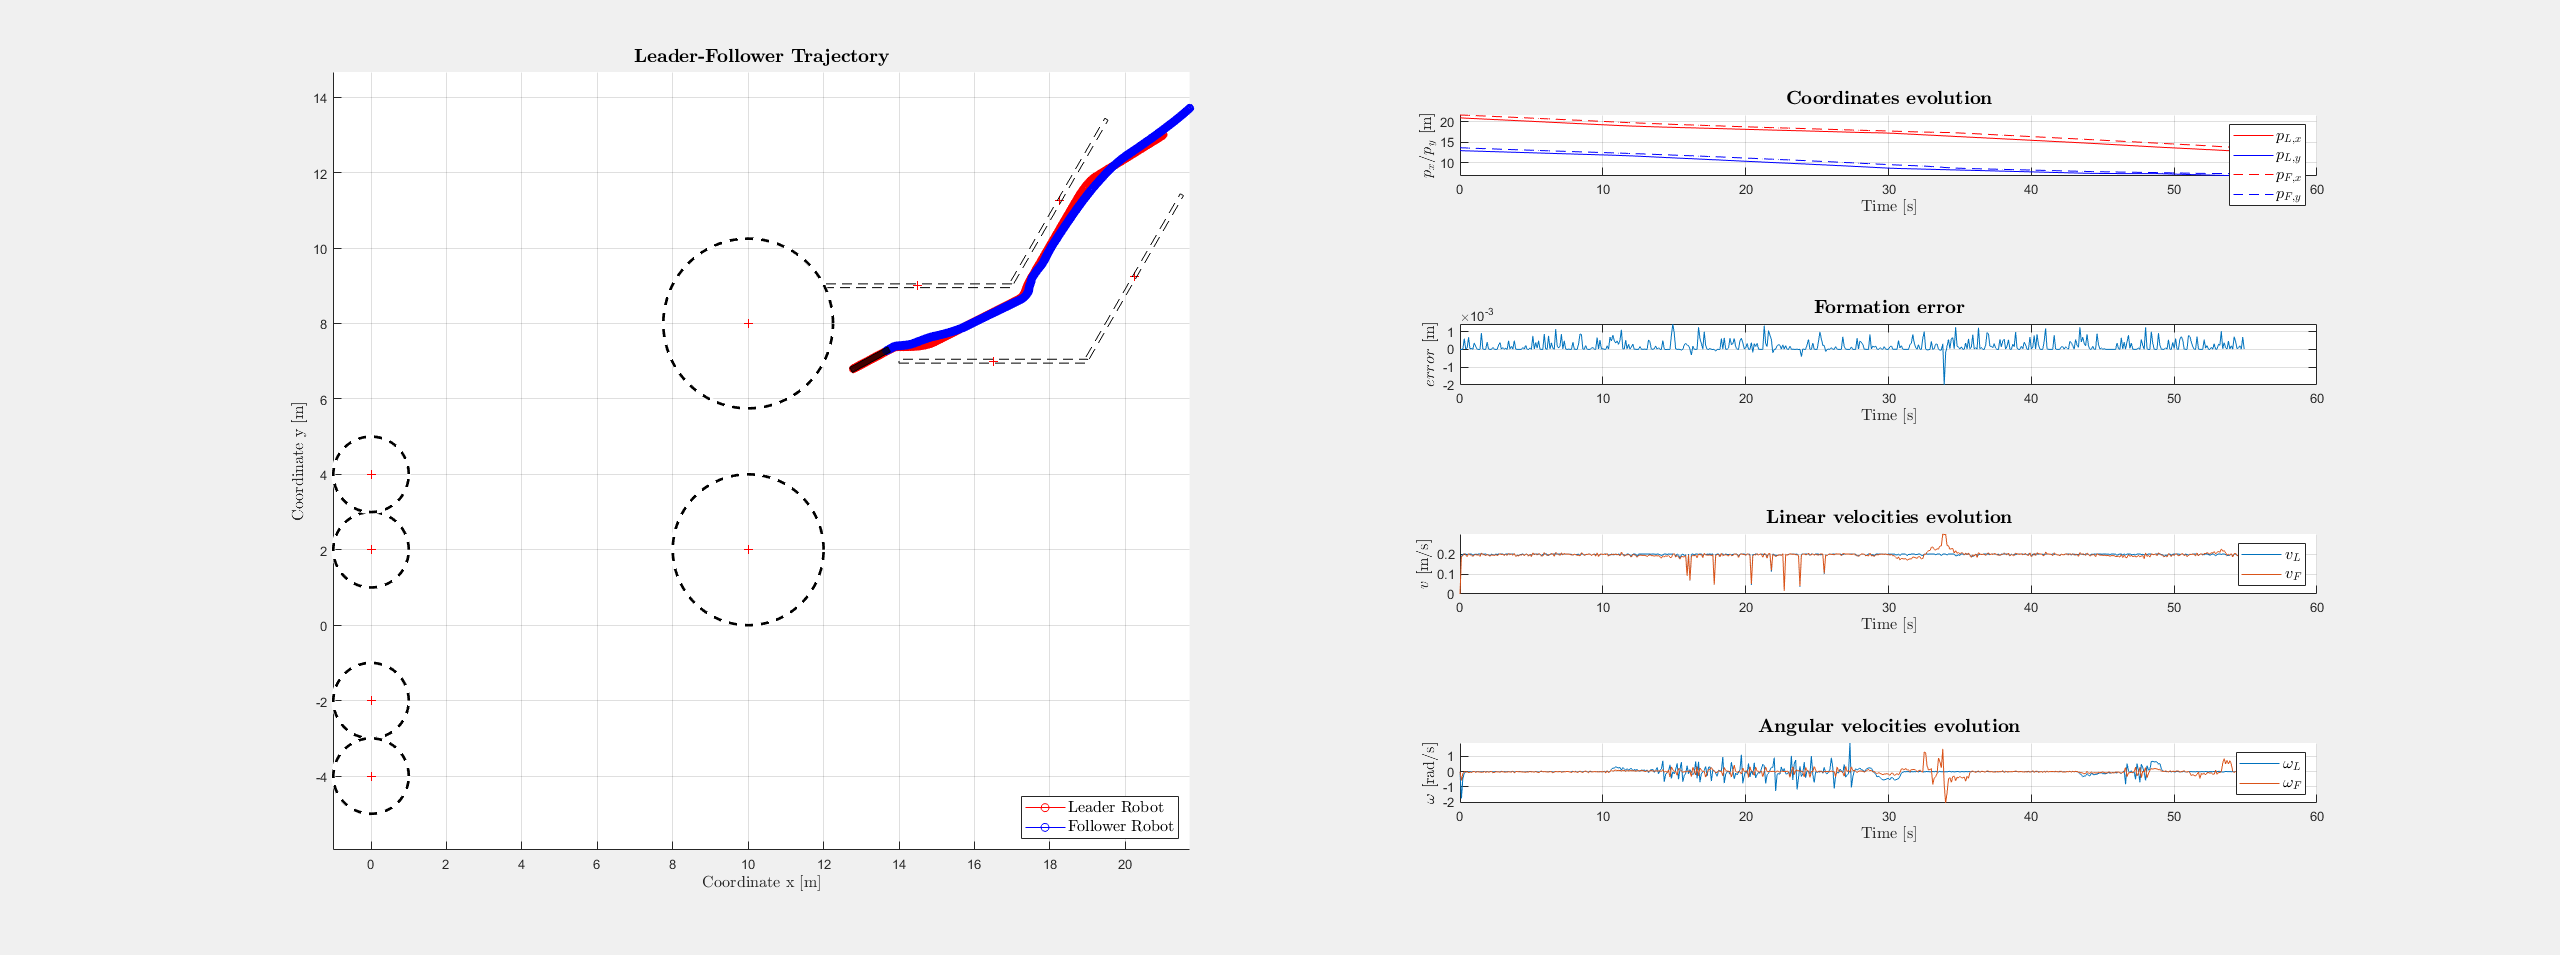

plotName = 'plot_' + environmentName + '.pdf'; 
plotPath = fullfile(folderName, plotName);
print(hFig, plotPath, '-dpdf', '-r600', '-bestfit');